clear
load('usps_all');

reduce_dim = false;
X = double(reshape(data,256,11000)');
ylabel = [1:9 0];

y = reshape(repmat(ylabel,1100,1),11000,1);

clearvars data

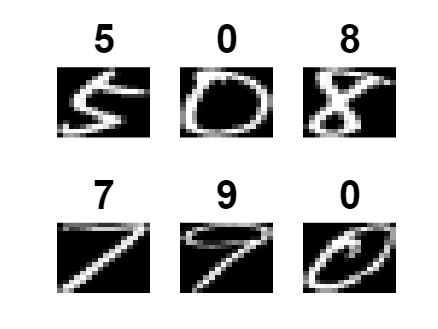

figure(1)
for ii = 1:6
    subplot(2,3,ii)
    rand_num = randperm(11000,1);
    image(reshape(X(rand_num,:),16,16))
    title((y(rand_num)),'FontSize',20)
    axis off
end
colormap gray

cv = cvpartition(y, 'holdout', .5);
Xtrain = X(cv.training,:);

Ytrain = y(cv.training,1);

Xtest = X(cv.test,:);
Ytest = y(cv.test,1);

mdl_ctree = ClassificationTree.fit(Xtrain,Ytrain);
ypred = predict(mdl_ctree,Xtest);
Confmat_ctree = confusionmat(Ytest,ypred);

mdl = fitensemble(Xtrain,Ytrain,'bag',200,'tree','type','Classification');
ypred = predict(mdl,Xtest);
Confmat_bag = confusionmat(Ytest,ypred);

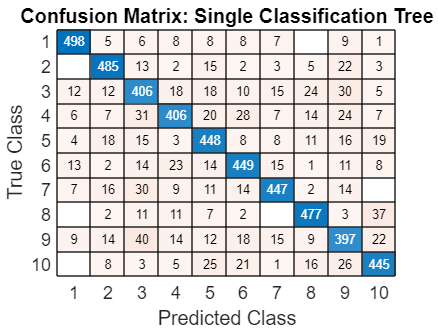

figure
confusionchart(Confmat_ctree)
title('Confusion Matrix: Single Classification Tree')

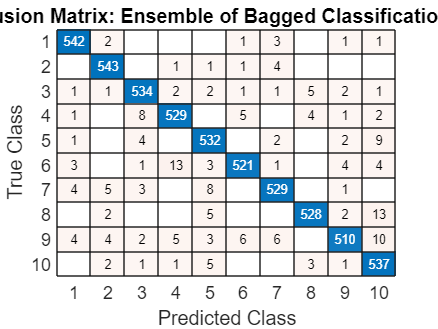

figure
confusionchart(Confmat_bag)
title('Confusion Matrix: Ensemble of Bagged Classification Trees')